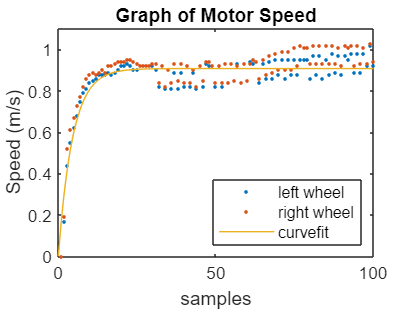

data = csvread('motorData.csv');
leftWheel = (data(:,1));
rightWheel = (data(:,2));
figure()
plot(leftWheel, '.')
hold on
plot(rightWheel,'.')


a = 0.003023;
tau = 4.53;
fplot(@(x) 300*a*(1-exp(-x/tau)))
% Values from curvefitter
ylim([0 1.1])
xlim([0,100])
title("Graph of Motor Speed")
ylabel("Speed (m/s)")
xlabel("samples")
legend('left wheel', 'right wheel', 'curvefit', location='southeast')